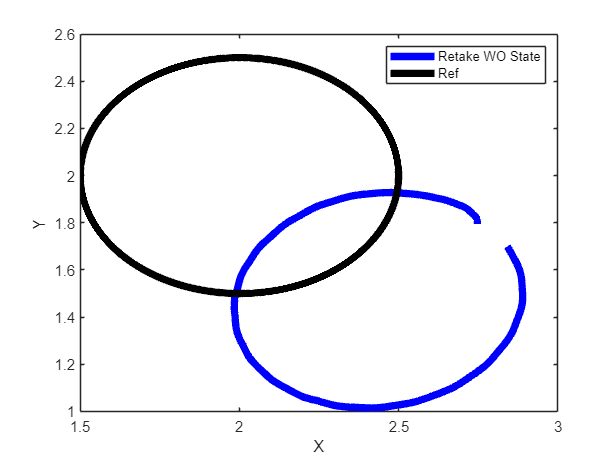

clear; % clears all var
clc; % clears command window
data_ref = load("ref.mat");
data_cw = load("retake_one.mat");
%data_ccw = load("ccw_video.mat");
%data = load("first_successful.mat");

start = 80;
last = 400; 

x_cw = (data_cw.retake_one(start:last,1));
y_cw = (data_cw.retake_one(start:last,2));
z_cw = (data_cw.retake_one(:,3));
heading = rad2deg((data_cw.retake_one(start:last,4))); % 1 round in control inputs is 80 pts, but reality wise is 320 pts for some reason
a = size(heading);

x_r = (data_ref.C3(11,:));
y_r = (data_ref.C3(12,:));
z_r = (data_ref.C3(13,:));

figure(1)
plot(x_cw,y_cw,'Color','blue','linewidth',5)

hold on

plot(x_r,y_r,'Color','black','linewidth',5)

xlabel('X')
ylabel('Y')
legend('Retake WO State','Ref')
hold off

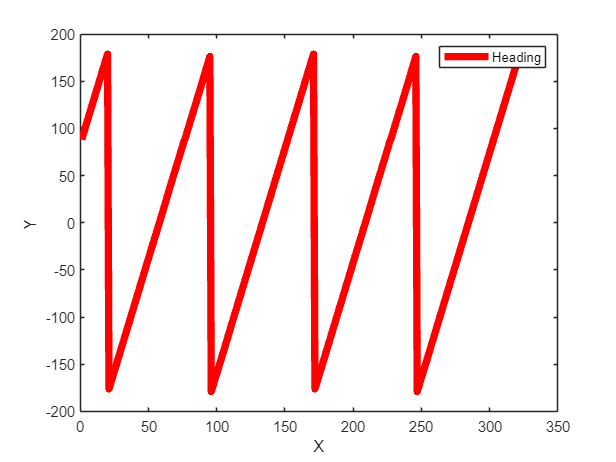


plot(1:a(1),heading,'Color','red','linewidth',5)

xlabel('X')
ylabel('Y')
legend('Heading')

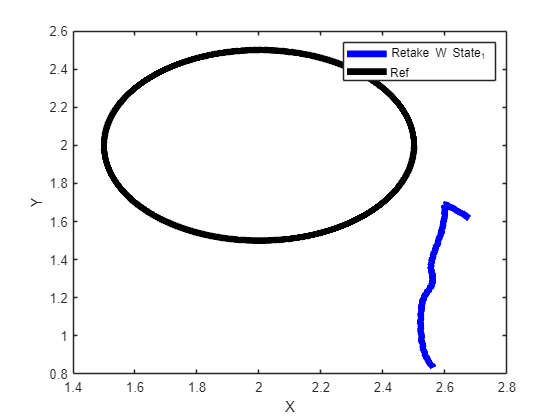

clear; % clears all var
clc; % clears command window
data_ref = load("ref.mat");
data_cw = load("retake_one_state.mat");
%data_ccw = load("ccw_video.mat");
%data = load("first_successful.mat");

x_cw = (data_cw.retake_one_state(1:420,1));
y_cw = (data_cw.retake_one_state(1:420,2));
z_cw = (data_cw.retake_one_state(:,3));
heading = rad2deg((data_cw.retake_one_state(1:420,4)));
a = size(heading);

x_r = (data_ref.C3(11,:));
y_r = (data_ref.C3(12,:));
z_r = (data_ref.C3(13,:));

figure(1)
plot(x_cw,y_cw,'Color','blue','linewidth',5)

hold on

plot(x_r,y_r,'Color','black','linewidth',5)

xlabel('X')
ylabel('Y')
legend('Retake W State_1','Ref')
hold off

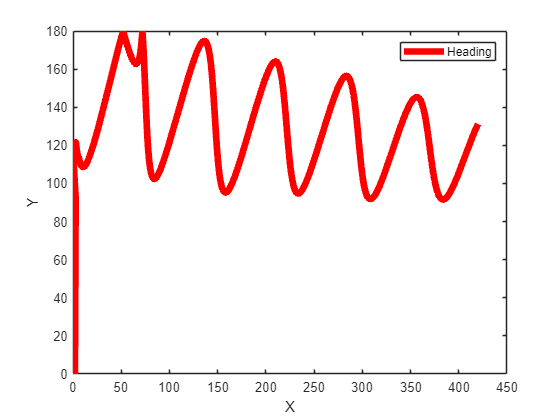


plot(1:a(1),abs(heading),'Color','red','linewidth',5)

xlabel('X')
ylabel('Y')
legend('Heading')

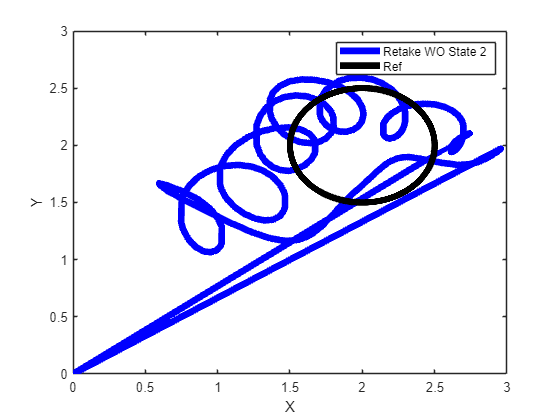

clear; % clears all var
clc; % clears command window
data_ref = load("ref.mat");
data_cw = load("retake_two.mat");
%data_ccw = load("ccw_video.mat");
%data = load("first_successful.mat");

x_cw = (data_cw.retake_two(:,1));
y_cw = (data_cw.retake_two(:,2));
z_cw = (data_cw.retake_two(:,3));
heading = rad2deg((data_cw.retake_two(1:420,4)));
a = size(heading);

x_r = (data_ref.C3(11,:));
y_r = (data_ref.C3(12,:));
z_r = (data_ref.C3(13,:));

figure(1)
plot(x_cw,y_cw,'Color','blue','linewidth',5)

hold on

plot(x_r,y_r,'Color','black','linewidth',5)

xlabel('X')
ylabel('Y')
legend('Retake WO State 2','Ref')
hold off

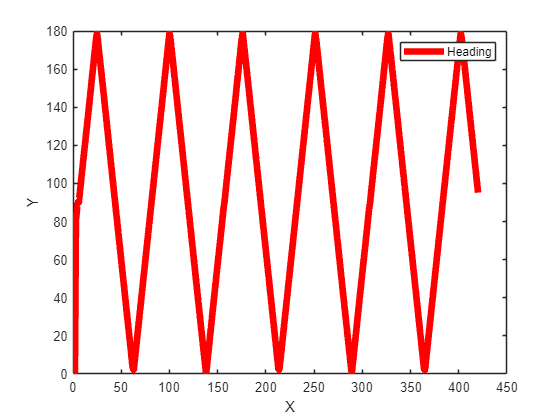


plot(1:a(1),abs(heading),'Color','red','linewidth',5)

xlabel('X')
ylabel('Y')
legend('Heading')

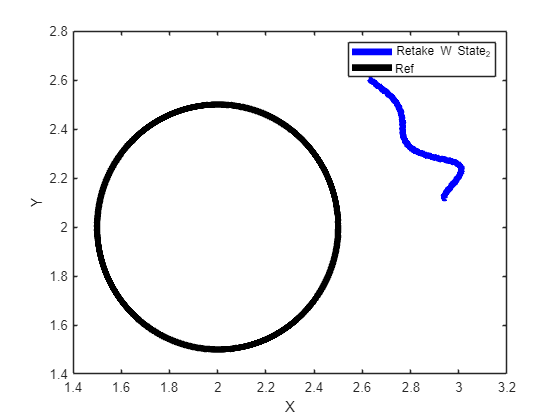

clear; % clears all var
clc; % clears command window
data_ref = load("ref.mat");
data_cw = load("retake_two_state.mat");
%data_ccw = load("ccw_video.mat");
%data = load("first_successful.mat");

x_cw = (data_cw.retake_two_state(1:420,1));
y_cw = (data_cw.retake_two_state(1:420,2));
z_cw = (data_cw.retake_two_state(:,3));
heading = rad2deg((data_cw.retake_two_state(1:420,4)));
a = size(heading);

x_r = (data_ref.C3(11,:));
y_r = (data_ref.C3(12,:));
z_r = (data_ref.C3(13,:));

figure(1)
plot(x_cw,y_cw,'Color','blue','linewidth',5)

hold on

plot(x_r,y_r,'Color','black','linewidth',5)

xlabel('X')
ylabel('Y')
legend('Retake W State_2','Ref')
hold off

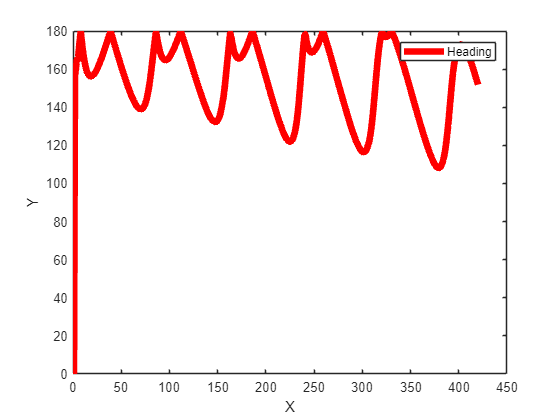


plot(1:a(1),abs(heading),'Color','red','linewidth',5)




xlabel('X')
ylabel('Y')
legend('Heading')